# `Detector de caracteres alfanúmericos mediante MSER y OCR.`

`1°) Visualización en escala de grises`

clear
clc
colorImage = imread("imagen1.png");
I = im2gray(colorImage);

` 2°) Aplicación de la técnica MSER`

`Esta función devuelve las regiones MSER detectadas (puede incluso, detectar zonas que no tiene texto).`

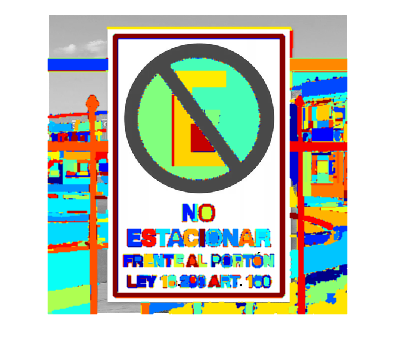

regions = detectMSERFeatures(I);
figure; imshow(I); hold on;
plot(regions,'showPixelList',true,'showEllipses',false);

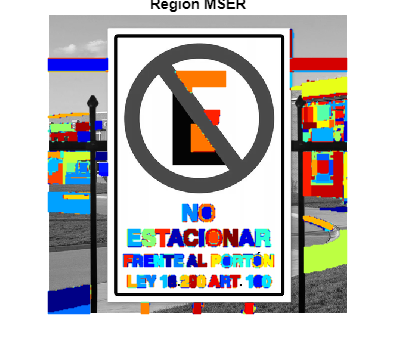


% RegionAreaRange utilizado en la imagen1: [100 4000], ThresholdDelta: 3.
% RegionAreaRange utilizado en la imagen2: [10 14000], ThresholdDelta: 1.
[mserRegions, mserConnComp] = detectMSERFeatures(I, "RegionAreaRange",[100 4000],"ThresholdDelta", 3);

figure
imshow(I)
hold on
plot(mserRegions, "showPixelList", true,"showEllipses",false)
title("Región MSER")
hold off

`3°) Eliminación de regiones que no sean texto`

`Para eliminar las regiones detectadas por el algoritmo MSER que no corresponden a texto, se pueden aplicar filtros basados en propiedades geométricas.`

`Número de euler, Excentricidad, grado y solidez`

mserStats = regionprops(mserConnComp, 'BoundingBox', 'Eccentricity','Solidity', 'Extent', 'Euler', 'Image');

`Relación de aspecto`

bbox = vertcat(mserStats.BoundingBox);
w = bbox(:,3);
h = bbox(:,4);
aspectRatio = w./h;

`Aplicación de filtros`

`Ya se han analizado los datos para identificar qué regiones deben eliminarse, y se aplicará una operación lógica para llevarlo a cabo.`

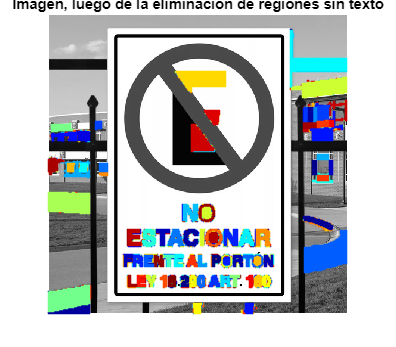

filterIdx = aspectRatio' > 3; 
filterIdx = filterIdx | [mserStats.Eccentricity] > .995 ;
filterIdx = filterIdx | [mserStats.Solidity] < .3;
filterIdx = filterIdx | [mserStats.Extent] < 0.2 | [mserStats.Extent] > 0.9;
filterIdx = filterIdx | [mserStats.EulerNumber] < -4;

% Eliminar región sin texto
mserStats(filterIdx) = [];
mserRegions(filterIdx) = [];

% Mostrar resultado de la eliminación
figure
imshow(I)
hold on
plot(mserRegions, 'showPixelList', true,'showEllipses',false)
title('Imagen, luego de la eliminacion de regiones sin texto')
hold off

`Basado en la variación del grosor del trazo`

`Se usa el grosor del trazo como un criterio para distinguir entre texto y áreas no textuales.`

`Imagen Binaria`

`Para estimar el grosor del trazo en una región MSER, se utiliza una transformación de distancia junto con una operación de adelgazamiento binario.`

regionImage = mserStats(6).Image;
regionImage = padarray(regionImage, [1 1]); %relleno para evitar efectos de contorno 

% Calculo la imagen del ancho del trazo.
distanceImage = bwdist(~regionImage); 
skeletonImage = bwmorph(regionImage, 'thin', inf);

`Umbral de variación`

`Para eliminar las áreas que no corresponden a texto utilizando la variación del grosor del trazo, se establece un umbral según el estilo de la fuente. Este umbral puede necesitar ajustes según las diferentes imágenes.`

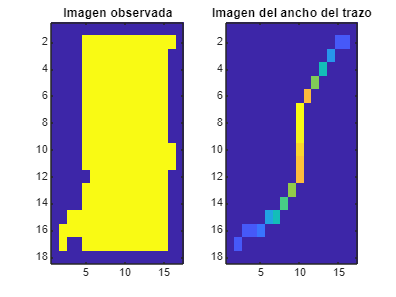

strokeWidthImage = distanceImage;
strokeWidthImage(~skeletonImage) = 0;

% Imagen observada e Imagen del ancho del trazo. 
figure
subplot(1,2,1)
imagesc(regionImage)
title('Imagen observada')

subplot(1,2,2)
imagesc(strokeWidthImage)
title('Imagen del ancho del trazo')

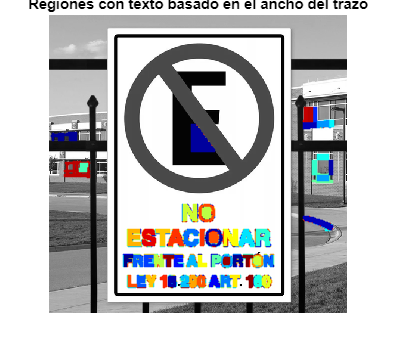


% Calcular la métrica de variación del ancho del trazo 
strokeWidthValues = distanceImage(skeletonImage);   
strokeWidthMetric = std(strokeWidthValues)/mean(strokeWidthValues);
% Umbral de la métrica de variación del ancho del trazo
strokeWidthThreshold = 0.4;
strokeWidthFilterIdx = strokeWidthMetric > strokeWidthThreshold;

% Procesar las regiones restantes 
for j = 1:numel(mserStats)
    
    regionImage = mserStats(j).Image;
    regionImage = padarray(regionImage, [1 1], 0);
    
    distanceImage = bwdist(~regionImage);
    skeletonImage = bwmorph(regionImage, 'thin', inf);
    
    strokeWidthValues = distanceImage(skeletonImage);
    
    strokeWidthMetric = std(strokeWidthValues)/mean(strokeWidthValues);
    
    strokeWidthFilterIdx(j) = strokeWidthMetric > strokeWidthThreshold;
    
end

% Eliminar regiones según la variación del ancho del trazo
mserRegions(strokeWidthFilterIdx) = [];
mserStats(strokeWidthFilterIdx) = [];

% Mostrar regiones restantes
figure
imshow(I)
hold on
plot(mserRegions, 'showPixelList', true,'showEllipses',false)
title('Regiones con texto basado en el ancho del trazo')
hold off

`4°) Combinaciones de regiones de texto`

`Se identifican las regiones de texto adyacentes y se crea un cuadro delimitador que las abarque.`

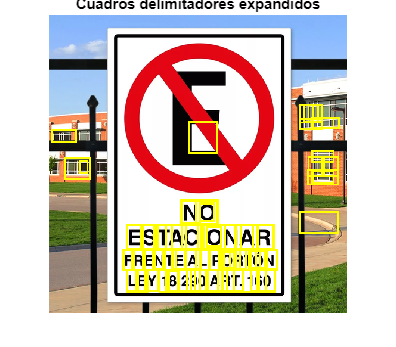

% Obtener cuadros delimitadores para todas las regiones
bboxes = vertcat(mserStats.BoundingBox);

%Convertir del formato de cuadro delimitador [xy ancho alto] al formato 
% [xmin ymin % xmax ymax] para mayor comodidad.
xmin = bboxes(:,1);
ymin = bboxes(:,2);
xmax = xmin + bboxes(:,3) - 1;
ymax = ymin + bboxes(:,4) - 1;

% Expandir los cuadros delimitadores en una pequeña cantidad.
expansionAmount = 0.02;
xmin = (1-expansionAmount) * xmin;
ymin = (1-expansionAmount) * ymin;
xmax = (1+expansionAmount) * xmax;
ymax = (1+expansionAmount) * ymax;

% Recortar los cuadros delimitadores para que estén dentro de los límites de la imagen
xmin = max(xmin, 1);
ymin = max(ymin, 1);
xmax = min(xmax, size(I,2));
ymax = min(ymax, size(I,1));

% Muestra de cuadros delimitadores expandidos
expandedBBoxes = [xmin ymin xmax-xmin+1 ymax-ymin+1];
IExpandedBBoxes = insertShape(colorImage,"rectangle",expandedBBoxes,"LineWidth",3);

figure
imshow(IExpandedBBoxes)
title('Cuadros delimitadores expandidos')

`Superposición de cuadros delimitadores`

`Los cuadros delimitadores superpuestos se pueden fusionar para formar un único cuadro delimitador alrededor de palabras individuales o líneas de texto. Para ello, calcule la relación de superposición entre todos los pares de cuadros delimitadores.`

% Calcular la relación de superposición 
overlapRatio = bboxOverlapRatio(expandedBBoxes, expandedBBoxes);

% Establecer la relación de superposición entre un cuadro delimitador y él mismo en cero
% para simplificar la representación del gráfico.
n = size(overlapRatio,1); 
overlapRatio(1:n+1:n^2) = 0;

% Crear gráfico
g = graph(overlapRatio);

% Encontrar las regiones de texto conectadas dentro del gráfico.
componentIndices = conncomp(g);

`Combinación`

`La función "conncomp" genera índices para cada región de texto conectada a la que pertenece un cuadro delimitador. Estos índices se pueden utilizar para fusionar múltiples cuadros delimitadores vecinos en un único cuadro delimitador. El proceso de fusión implica calcular el valor mínimo y máximo de las coordenadas de los cuadros delimitadores individuales que componen cada componente conectado.`

% Fusionar los cuadros según las dimensiones mínimas y máximas.
xmin = accumarray(componentIndices', xmin, [], @min);
ymin = accumarray(componentIndices', ymin, [], @min);
xmax = accumarray(componentIndices', xmax, [], @max);
ymax = accumarray(componentIndices', ymax, [], @max);

% Componer los cuadros delimitadores fusionados utilizando
% el formato [x y ancho alto]
textBBoxes = [xmin ymin xmax-xmin+1 ymax-ymin+1];


`5°) Resultados`

`Antes de mostrar los resultados de detección finales, se eliminan las detecciones de texto falsas. Esto se logra eliminando los cuadros delimitadores que solo contienen una región de texto. Esta eliminación se justifica porque las regiones aisladas rara vez corresponden a texto real, ya que el texto generalmente se encuentra en grupos (palabras, oraciones).`

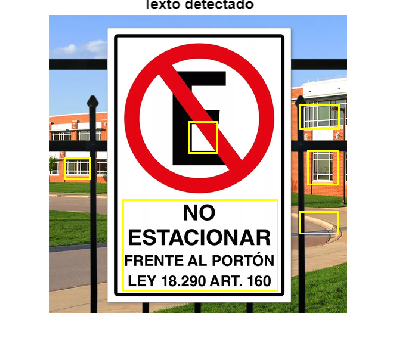

% Eliminar cuadros delimitadores que solo contienen una región de texto.
numRegionsInGroup = histcounts(componentIndices);
textBBoxes(numRegionsInGroup == 1, :) = [];

% Mostrar el resultado final de la detección de texto.
ITextRegion = insertShape(colorImage, "rectangle", textBBoxes,"LineWidth",3);

figure
imshow(ITextRegion)
title("Texto detectado")

`6°) Reconocer el texto detectado mediante OCR`

`Luego de identificar las regiones de texto, se emplea la función "ocr" para reconocer el texto contenido dentro de cada cuadro delimitador. Es importante destacar que, si no se realiza la detección previa de las regiones de texto, el resultado de la función "ocr" sería significativamente más impreciso (ruidoso).`

ocrtxt = ocr(I, textBBoxes);
[ocrtxt.Text]

ans =     ' 
     
     NO
     
     ESTACIONAR
     FRENTE AL PORTON
     LEY 18.290 ART. 160
     
     '
